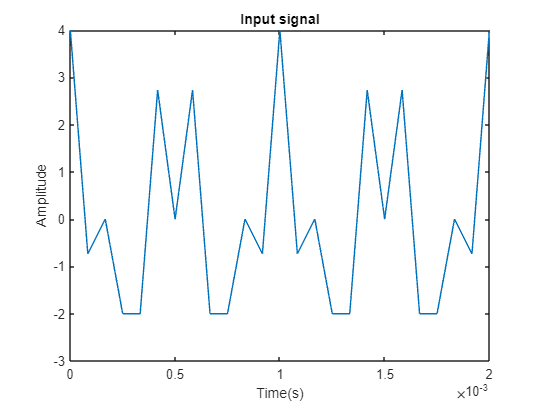

%input parameters
T=0.002;
N=256;
F = 1000;
Fs1 = 12000; %Sampling frequency
Fs2 = 24000;
Fc = 6000;  %cut-off frequency
t = 0:1/Fs1:T;


x =2*cos(2*5*pi*F*t)+2*cos(2*2*pi*F*t); %low pass input signal of bandwidth 6kHz
figure(1)
plot(t,x) %Plotting input signal
title('Input signal')
xlabel('Time(s)')
ylabel('Amplitude')

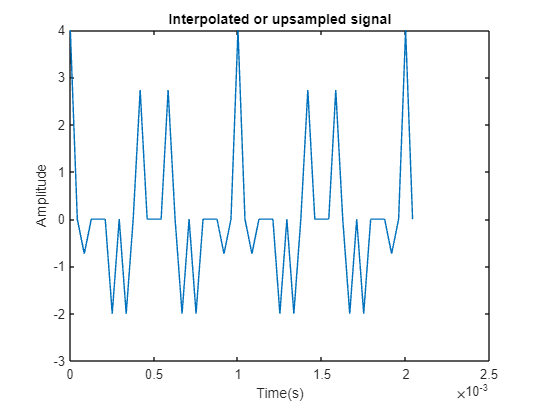


x_1 = upsample(x,2); %upsampling
t_1 = 0:(1/(2*Fs1)):T+ (1/(2*Fs1));
figure(2)
plot(t_1,x_1)
title('Interpolated or upsampled signal')%adding zeros distort the signal
xlabel('Time(s)')
ylabel('Amplitude')

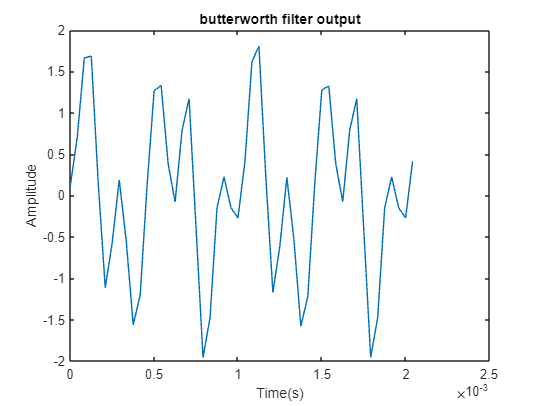


%Filters

%Butterworth filter - flat magnitude filter 
[b,a] = butter(6, Fc/(Fs2/2)); % 6th-order lowpass digital Butterworth
dataout = filter(b,a,x_1);
figure(3)
plot(t_1, dataout)
title('butterworth filter output')% obtained attenuated signal
xlabel('Time(s)')
ylabel('Amplitude')

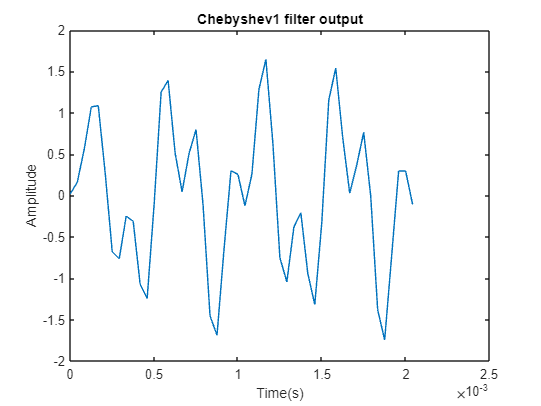


%Chebyshev1 Filter
[b,a] = cheby1(6,5, Fc/(Fs2/2)); %6th-order lowpass digital Chebyshev Type I filter with normalized passband edge frequency
output_cheby1= filter(b,a,x_1);
figure(4)
plot(t_1, output_cheby1)
title('Chebyshev1 filter output')% obtained attenuated signal
xlabel('Time(s)')
ylabel('Amplitude')

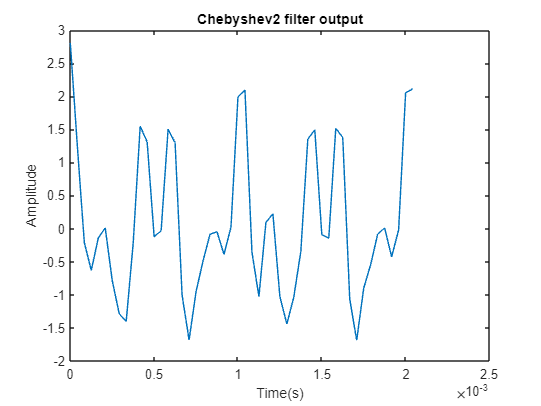


%Chebyshev2 filter
[b,a] = cheby2(6,2, Fc/(Fs2/2)); %6th-order lowpass digital Chebyshev Type II filter with normalized stopband edge frequency
output_cheby2= filter(b,a,x_1);
figure(5)
plot(t_1, output_cheby2)
title('Chebyshev2 filter output')% obtained attenuated signal
xlabel('Time(s)')
ylabel('Amplitude')

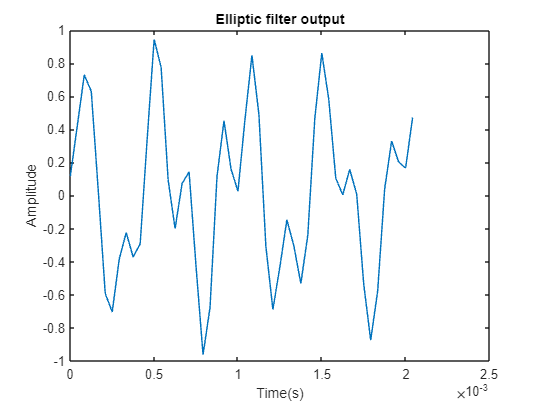


%Elliptic filter
[b,a] = ellip(6,10,50,Fc/(Fs2/2)); % 6th-order lowpass digital elliptic filter with normalized passband edge frequency
output_ellip= filter(b,a,x_1);
figure(6)
plot(t_1, output_ellip)
title('Elliptic filter output')% obtained attenuated signal
xlabel('Time(s)')
ylabel('Amplitude')

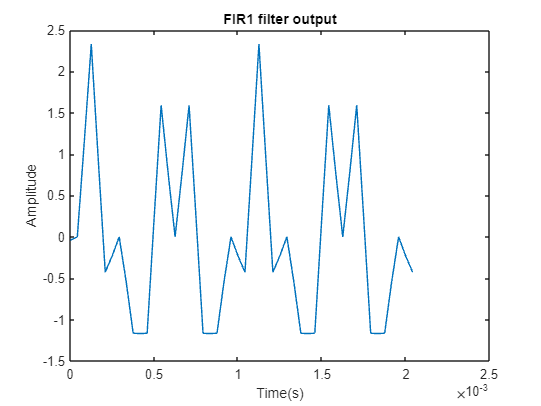


%FIR1
b=fir1(6,[0.0001,0.5]);%Hamming window used, 6th-order lowpass, with linear phase
fir1_output = filter(b,1, x_1);
figure(7)
plot(t_1, fir1_output)
title('FIR1 filter output')% obtained attenuated signal
xlabel('Time(s)')
ylabel('Amplitude')

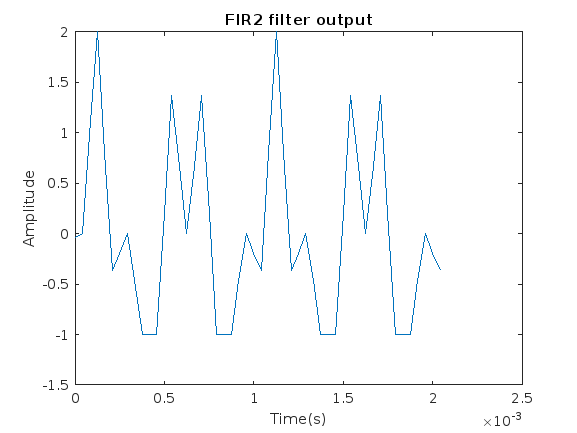



%FIR2
f=[0 0.5 0.5 1];%frequency
m=[1 1 0 0]; %magnitude
b=fir2(6,f,m); %6th-order FIR filter with frequency-magnitude characteristics 
fir2_output=filter(b,1,x_1);
figure(8)
plot(t_1, fir2_output)
title('FIR2 filter output')% obtained attenuated signal
xlabel('Time(s)')
ylabel('Amplitude')